test=rgb2gray(imread('betterer.jpg')); 

Error using imread>get_full_filename (line 481)
File "betterer.jpg" does not exist.

Error in imread (line 344)
    filename = get_full_filename(fid, errmsg, filename);

imshow(test)
size(test)

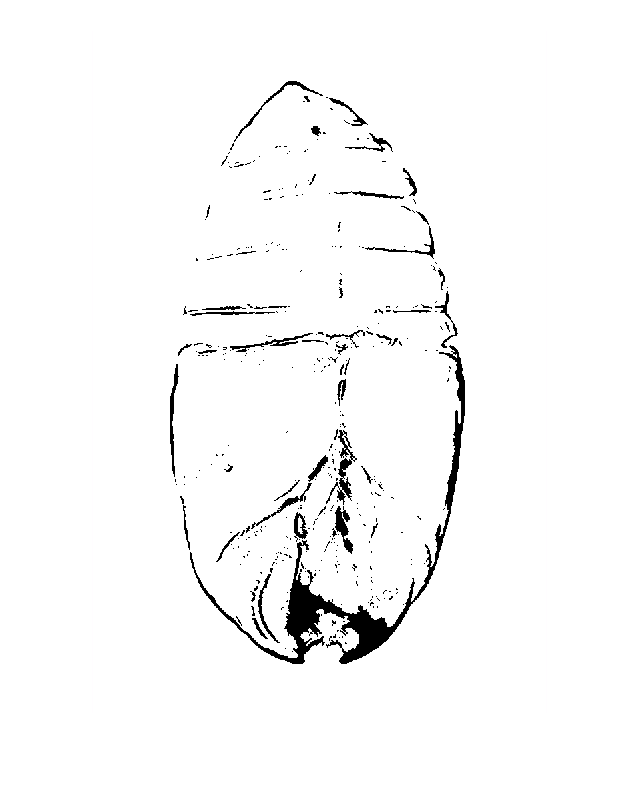

W= gradientweight(test, 4, 'RolloffFactor', 4, 'WeightCutoff', .3);
mask=false(size(test));
mask(1,1)=true;
segtest=imsegfmm(W,mask,0.24);
imclearborder(segtest);
imshow(segtest)

W1= gradientweight(test, 3, 'RolloffFactor', 4, 'WeightCutoff', .22);
mask1=false(size(test));
mask1(1,1)=true;
segtest1=imsegfmm(W1,mask1,0.24);
imclearborder(segtest1);
imshow(segtest1)